# Notas de clase: Sistemas Lineales

## Clase 1: Presentación del curso

## Clase 2: Repaso de ecuaciones diferenciales ordinarias

symsclear,clc

### Definiciones

- **Ecuación diferencial: **Ecuación que contiene derivadas

- **Ecuación diferenciales ordinarias: **Aplicación de las ecuaciones diferenciales a sistemas donde los parámetros son concentrados (todas las propiedades del sistema se resumen a un punto, es decir, se minimizan las variables independientes necesarias). **Ejemplo: **$f\left(t,y,\overset{\ldotp }{y} ,\overset{\ldotp \ldotp }{y} ,\ldotp \ldotp \ldotp ,\overset{\left(n\right)}{y} \right)=0,\;\;\;\;\overset{\ldotp }{y} =\frac{\mathrm{d}}{\mathrm{d}t}y$

- **Ecuaciones diferenciales parciales: **Aplicación a sistemas con parámetros distribuidos (las propiedades del sistema requieren más de una variable para expresarse)

- **Ecuaciones lineales: **Se dice que una ecuación diferencial de n-ésimo orden es lineal si $f\left(t,y,\overset{\ldotp }{y} ,\overset{\ldotp \ldotp }{y} ,\ldotp \ldotp \ldotp ,\overset{\left(n\right)}{y} \right)$ es lineal en $y,\overset{\ldotp }{y} ,\overset{\ldotp \ldotp }{y} ,\ldotp \ldotp \ldotp ,\overset{\left(n\right)}{y}$. Dicho de otra forma, la ecuación diferencial de n-ésimo orden es lineal si tiene la forma $a_n \left(t\right)\overset{\left(n\right)}{y} +\ldotp \ldotp \ldotp +a_0 \left(t\right)y=u\left(t\right)$.

- **Ecuaciones lineales con coeficientes constantes: **Se les conoce como **LTI **(Linear-Time-Invariant). Los coeficientes que acompañan a la variable dependiente no cambian con el tiempo, por tanto, son de la forma $a_n \overset{\left(n\right)}{y} +\ldotp \ldotp \ldotp +a_0 y=u\left(t\right)\ldotp$ Existen métodos analíticos para resolver estas ecuaciones. El término $u\left(t\right)$tiene significado como la entrada del sistema.

- **Problema de valor inicial: **Es un problema de la forma $\left\lbrace \begin{array}{ll}
\overset{\left(n\right)}{y} +a_1 \overset{\left(n-1\right)}{y} +\ldotp \ldotp \ldotp +a_n y=u\left(t\right) & \\
y\left(0\right)=y_{01} ,\ldotp \ldotp \ldotp ,\overset{\left(n-1\right)}{y\left(0\right)} =y_{0n}  & 
\end{array}\right.$

- **Solución general de un problema de valor inicial: **Se calcula la solución general como la suma de la solución de la ecuación complementaria homogénea ($y_c$) y una solución particular de la ecuación no homogénea ($y_p$). De forma tal, la solución general viene dada por $y\left(t\right)=y_c \left(t\right)+y_p \left(t\right)$.

- **Solución **$y_c \left(t\right)$**de la ecuación homogénea **($u\left(t\right)=0$)**: **Se obtiene el polinomio característico y se resuelve para obtener los valores característicos. Debe lidiarse con los casos de valores característicos reales diferentes, complejos diferentes y raíces múltiples. El polinomio característico de $\overset{\left(n\right)}{y} +a_1 \overset{\left(n-1\right)}{y} +\ldotp \ldotp \ldotp +a_n y=u\left(t\right)$ es de la forma $\lambda^n +a_1 \lambda^{n-1} +\ldotp \ldotp \ldotp +a_{n-1} \lambda +a_n =0$.

- **Solución **$y_p \left(t\right)$**de la ecuación no homogénea: **Se puede resolver aplicando el método de coeficientes indeterminados (método especial pero simple) o el método de variación de parámetros (método general pero complejo). Para ambos métodos consultar el libro de [Dennis G. Zill & Warren S. Wright](https://www.booksfree.org/differential-equation-by-dennis-g-zill/).

### Ejemplos

#### 1) La ecuación diferencial como definición de un campo vectorial

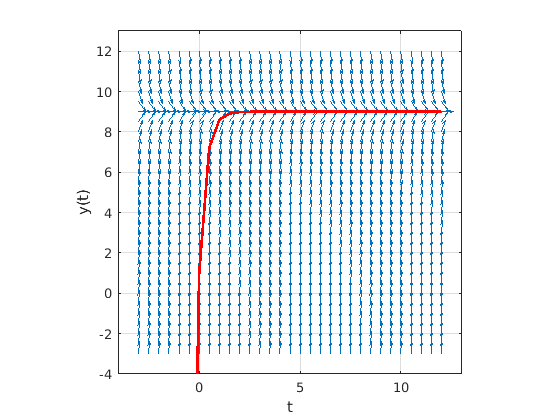

t=-3:0.5:12; y=-3:0.5:12; % define grid of values in t and y directions
[T,Y]=meshgrid(t,y); % creates 2d matrices
dT=ones(size(T)); % dt=1 for all points
dY=27-3*Y; % dy=(t^2-y)*dt: this is the ODE
N=sqrt(dT.^2+dY.^2); % magnitude of arrows
dT=dT./N; % normalize arrows to get all same length
dY=dY./N;
figure(1)
clf
quiver(T,Y,dT,dY) % draw arrows (t,y) --> (t+dt,y+dy)
axis equal
axis([-4 13 -4 13]) % repeat adjustments...
grid on
hold on
C1=8;
y=9-C1*exp(-3*t);
plot(t,y,'r','LineWidth',2);
hold off
xlabel('t')
ylabel('y(t)')

#### 2) Solución de ecuación homogénea

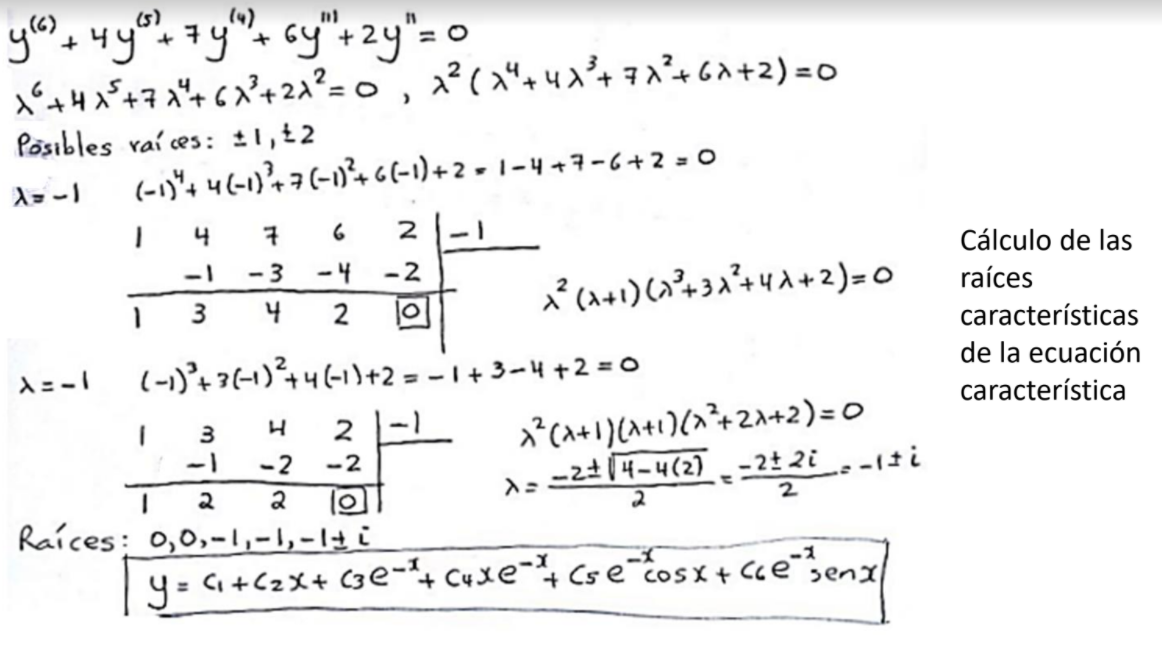

**Comprobación de la solución en MatLab**

syms y(x)
ode=diff(y,6)+4*diff(y,5)+7*diff(y,4)+6*diff(y,3)+2*diff(y,2)==0

$$ode(x) = \frac{\partial^{6}}{\partial x^{6}}y\left(x\right)+4\,\frac{\partial^{5}}{\partial x^{5}}y\left(x\right)+7\,\frac{\partial^{4}}{\partial x^{4}}y\left(x\right)+6\,\frac{\partial^{3}}{\partial x^{3}}y\left(x\right)+2\,\frac{\partial^{2}}{\partial x^{2}}y\left(x\right)=0$$

ySol(x) = dsolve(ode)

$$ySol(x) = C_{2}-\frac{3\,C_{1}}{2}+\frac{C_{1}\,x}{2}+C_{3}\,{\mathrm{e}}^{-x}+C_{4}\,x\,{\mathrm{e}}^{-x}+C_{5}\,{\mathrm{e}}^{-x}\,\cos\left(x\right)-C_{6}\,{\mathrm{e}}^{-x}\,\sin\left(x\right)$$

#### 3) Solución de ecuación no homogénea

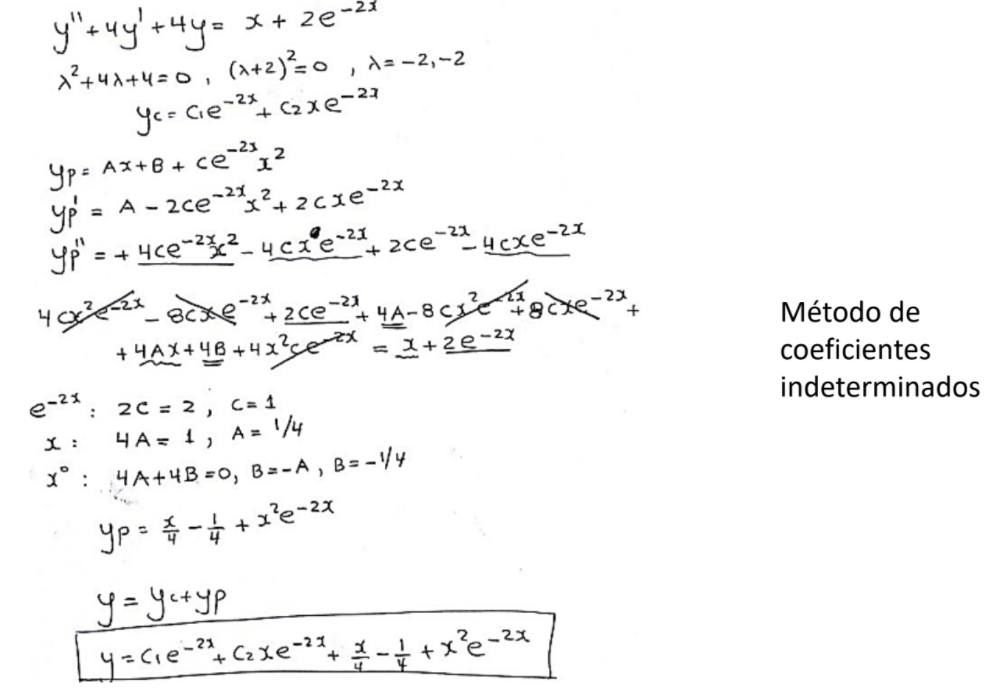

**Comprobación de la solución en MatLab**

ode2=diff(y,2)+4*diff(y)+4*y==x+2*exp(-2*x)

$$ode2(x) = \frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+4\,\frac{\partial }{\partial x}y\left(x\right)+4\,y\left(x\right)=x+2\,{\mathrm{e}}^{-2\,x}$$

ySol2(x) = simplify(dsolve(ode2))

$$ySol2(x) = \frac{x}{4}+x^{2}\,{\mathrm{e}}^{-2\,x}+C_{1}\,{\mathrm{e}}^{-2\,x}+C_{2}\,x\,{\mathrm{e}}^{-2\,x}-\frac{1}{4}$$

**Solución con condiciones iniciales**

y_0=2; y_1=3;
conds = [y(0)==y_0; y(1)==y_1];
ySol3(x)=dsolve(ode2,conds)

$$ySol3(x) = \frac{{\mathrm{e}}^{-2\,x}\,\left(x\,{\mathrm{e}}^{2\,x}-{\mathrm{e}}^{2\,x}-13\,x+12\,x\,{\mathrm{e}}^{2}+4\,x^{2}+9\right)}{4}$$

## Clase 3: Ecuaciones en diferencias

clear;clc

### Definiciones

- **Ecuación en diferencias: **Es una ecuación que contiene diferencias ($\Delta$).

- **Diferencias hacia adelante: **$\Delta y\left(\textrm{kT}\right)=\frac{y\left(\left(k+1\right)T\right)-y\left(\textrm{kT}\right)}{T}$,  $\overset{\left(2\right)}{\Delta} y\left(\textrm{kT}\right)=\frac{\Delta y\left(\left(k+1\right)T\right)-\Delta y\left(\textrm{kT}\right)}{T}=\frac{y\left(\left(k+2\right)T\right)-2y\left(\left(k+1\right)T\right)+y\left(\textrm{kT}\right)}{T^2 }$

- **Diferencias hacia atrás: **$\Delta y\left(\textrm{kT}\right)=\frac{y\left(\textrm{kT}\right)-y\left(\left(k-1\right)T\right)}{T}$,  $\overset{\left(2\right)}{\Delta} y\left(\textrm{kT}\right)=\frac{\Delta y\left(\textrm{kT}\right)-\Delta y\left(\left(k-1\right)T\right)}{T}=\frac{y\left(\textrm{kT}\right)-2y\left(\left(k-1\right)T\right)+y\left(\left(k-2\right)T\right)}{T^2 }$

- **Forma canónica de una ecuación en diferencias hacia adelante: **Se obtiene luego de simplificar $\Delta$ y reemplazar $T$, $\left\lbrace \begin{array}{ll}
y\left(k+n\right)+a_1 y\left(k+n-1\right)+\ldotp \ldotp \ldotp +a_n y\left(k\right)=u\left(k\right) & \\
y\left(0\right)=y_{01} ,y\left(1\right)=y_{02} ,\ldotp \ldotp \ldotp ,y\left(n-1\right)=y_{0n}  & 
\end{array}\right.$

- **Forma canónica de una ecuación en diferencias hacia atrás: **Se obtiene luego de simplificar $\Delta$ y reemplazar $T$, $\left\lbrace \begin{array}{ll}
y\left(k\right)+a_1 y\left(k-1\right)+\ldotp \ldotp \ldotp +a_n y\left(k-n\right)=u\left(k\right) & \\
y\left(0\right)=y_{01} ,y\left(-1\right)=y_{02} ,\ldotp \ldotp \ldotp ,y\left(-n\right)=y_{0n}  & 
\end{array}\right.$

### Ecuación en diferencias a partir de una ecuación diferencial:

Supongamos que deseamos discretizar la ecuación $\frac{d}{\mathrm{d}t}y+\textrm{ay}=u\left(t\right),y\left(0\right)=y_0$, para ello debemos notar que $\frac{d}{\mathrm{d}t}y\simeq \frac{y\left(k\right)-y\left(k-1\right)}{T}$ (diferencias hacia atrás) y por ende podemos reescribir la ecuación como $\frac{y\left(k\right)-y\left(k-1\right)}{T}+\textrm{ay}\left(k-1\right)=u\left(\left(\left(k-1\right)T\right.\right)\Longrightarrow y\left(k\right)+\left(\textrm{aT}-1\right)y\left(k-1\right)=\textrm{Tu}\left(\left(k-1\right)T\right)$, de forma tal, el problema original se convierte en $\left\lbrace \begin{array}{ll}
y\left(k\right)=\left(1-\textrm{aT}\right)y\left(k-1\right)+\textrm{Tu}\left(\left(k-1\right)T\right) & \\
y\left(0\right)=y_0  & 
\end{array}\right.$

#### Ejemplo: Ecuación en diferencias hacia atrás de orden 2

Resolver la ecuación en diferencias dada por $\left\lbrace \begin{array}{ll}
y\left(k\right)+0\ldotp 9y\left(k-1\right)+0\ldotp 14y\left(k-2\right)=0\ldotp 3u\left(k-1\right)-0\ldotp 6u\left(k-2\right), & u\left(k\right)=\delta \left(k-1\right)=\left\lbrace \begin{array}{ll}
1 & k=1\\
0 & k\not= 1
\end{array}\right.\\
y\left(0\right)=y\left(1\right)=0 & 
\end{array}\right.$

Solucionamos aprovechando la relación de recurrencia:


$$\begin{array}{l}
y\left(k\right)=-0\ldotp 9y\left(k-1\right)-0\ldotp 14y\left(k-2\right)+0\ldotp 3\delta \left(k-2\right)-0\ldotp 6\delta \left(k-3\right)\\
y\left(2\right)=-0\ldotp 9y\left(1\right)-0\ldotp 14y\left(0\right)+0\ldotp 3\delta \left(0\right)-0\ldotp 6\delta \left(-1\right)=0\ldotp 3\\
y\left(3\right)=-0\ldotp 9y\left(2\right)-0\ldotp 14y\left(1\right)+0\ldotp 3\delta \left(1\right)-0\ldotp 6\delta \left(0\right)=-0\ldotp 9\left(0\ldotp 3\right)-0\ldotp 6=-0\ldotp 87\\
\vdots 
\end{array}$$


**Nota: **Es posible utilizar más de un método de discretización para aproximar las derivada, por ejemplo el método de Runge-Kutta4 o el método de Heun.

#### Comparación entre solución discretizada y la solución de la ecuación diferencial discretizada

Supongamos que tenemos la ecuación $\frac{d}{\mathrm{d}t}y+\textrm{ay}=e^{-t} ,\;y\left(0\right)=2$, al discretizar con $T$ llegamos a la expresión $\left\lbrace \begin{array}{ll}
y\left(k\right)=\left(1-\textrm{aT}\right)y\left(k-1\right)+{\textrm{Te}}^{-T\left(k-1\right)}  & \\
y\left(0\right)=y_o  & 
\end{array}\right.$. Para resolver esta ecuación en el intervalo $\left\lbrack 0\;,10\right\rbrack$ podemos implementar el siguiente código

T=0.21;
a=1;
y_0=-4;
time=0:T:10;

%%%% Solución continua
syms y(t)
ode = diff(y)+a*y-exp(-t)==0

$$ode(t) = \frac{\partial }{\partial t}y\left(t\right)-{\mathrm{e}}^{-t}+y\left(t\right)=0$$

cond = y(0)==y_0;
ySol(t)=dsolve(ode,cond)

$$ySol(t) = {\mathrm{e}}^{-t}\,\left(t-4\right)$$

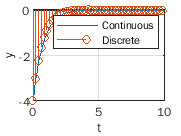


%%%% Solución discreta
yDis=t;
yCont=yDis;
yDis(1)=y_0;
for k=[1:length(time)-1]+1
    yDis(k)=(1-a*T)*yDis(k-1)+T*exp(-T*(k-1));
end

%%%%%%% Comparación entre soluciones
figure(1)
clf
fplot(ySol,[0 10])
grid on
hold on
stem(time,vpa(yDis))
xlabel('t')
ylabel('y')
legend({'Continuous','Discrete'})

#### T implícito vs T explícito

Una vez se ha obtenido la ecuación en diferencias a partir de la ecuación diferencial es posible omitir el instante en el tiempo y concentrarse solo en el número de muestreo actual (T implícito). Para graficar adecuadamente es necesario recordar que $t=\textrm{kT}$.

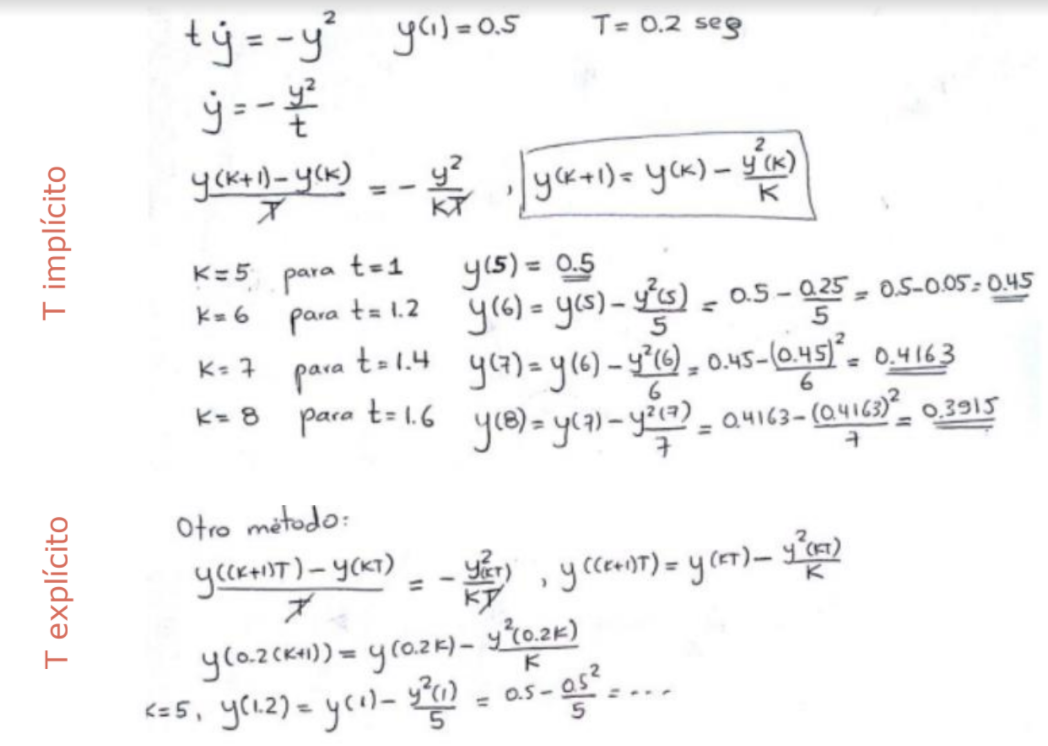

### Solución analítica de una ecuación en diferencias

De la misma forma que se pueden solucionar las ecuaciones diferenciales LTI, es posible plantear un problema de autovalores para las ecuaciones en diferencias. Sea tal solución $\phi =e^{\gamma k}$, reemplazamos en la ecuación en diferencias  $y\left(k+n\right)+a_1 y\left(k+n-1\right)+\ldotp \ldotp \ldotp +a_n y\left(k\right)=0$ para obtener $e^{\gamma \left(k+n\right)} +a_1 e^{\gamma \left(k+n-1\right)} +\ldotp \ldotp \ldotp +a_n e^{\gamma k} =0\Longrightarrow e^{\gamma k} \left(e^{\gamma n} +a_1 e^{\gamma \left(n-1\right)} +\ldotp \ldotp \ldotp +a_n \right)=0$, ahora, introduciendo el cambio de variable $\lambda =e^{\gamma }$ tenemos que $e^{\gamma k} \left(e^{\gamma n} +a_1 e^{\gamma \left(n-1\right)} +\ldotp \ldotp \ldotp +a_n \right)=\lambda^k \left(\lambda^n +a_1 \lambda^{n-1} +\ldotp \ldotp \ldotp +a_n \right)=0\Longrightarrow \lambda^n +a_1 \lambda^{n-1} +\ldotp \ldotp \ldotp +a_n =0$, lo cual se cumplirá para $\lambda \in \left\lbrace \lambda_1 ,\ldotp \ldotp \ldotp ,\lambda_n \right\rbrace$. Resta notar entonces que $\phi =e^{\gamma k} =\lambda^k$ para encontrar las soluciones de la ecuación.

#### Primer ejemplo de solución analítica

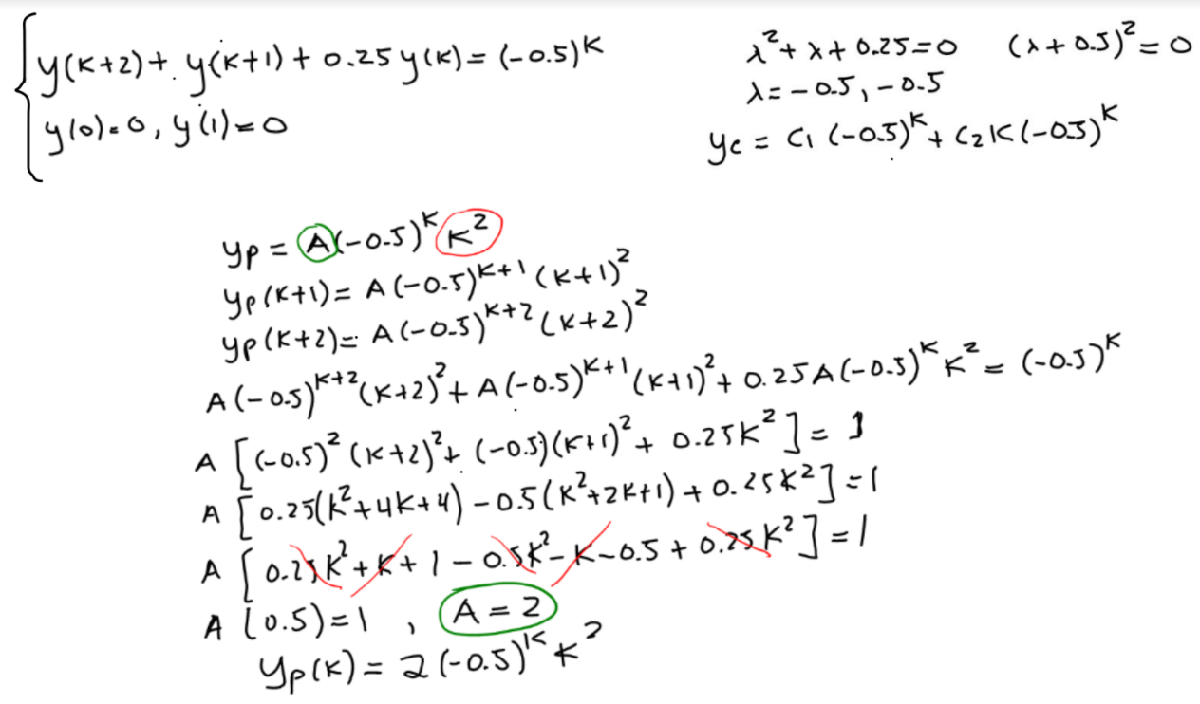

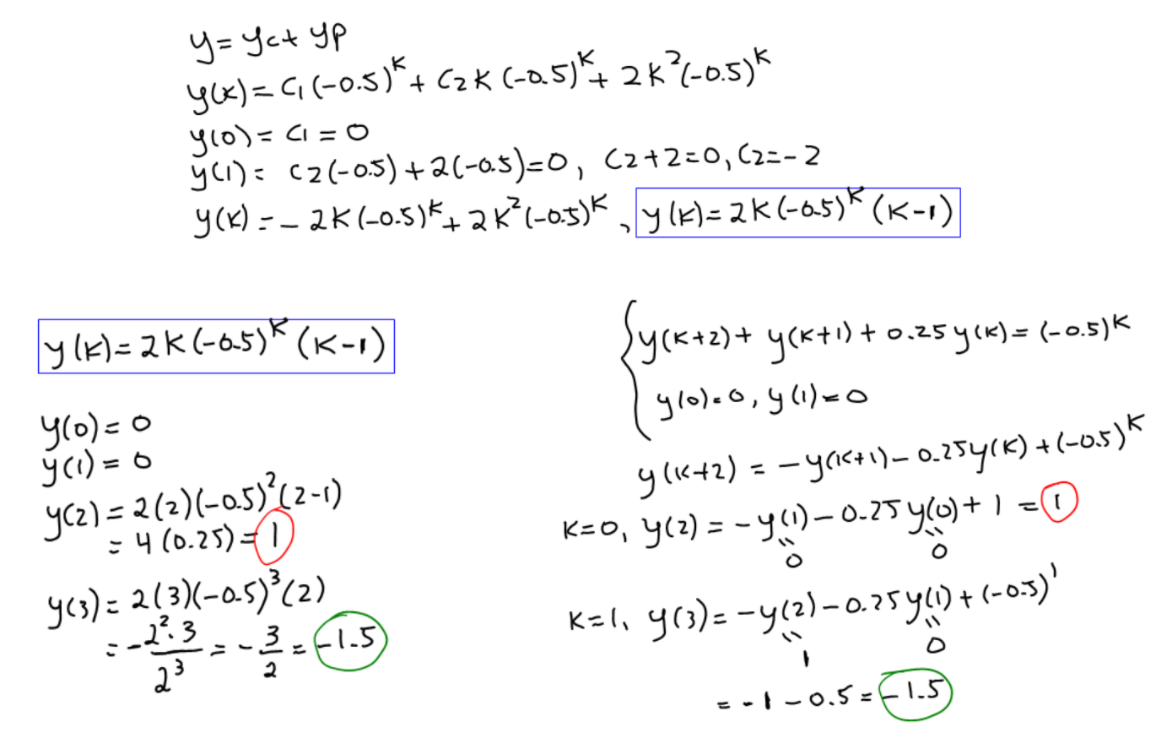

#### Segundo ejemplo de solución analítica: lambda imaginario

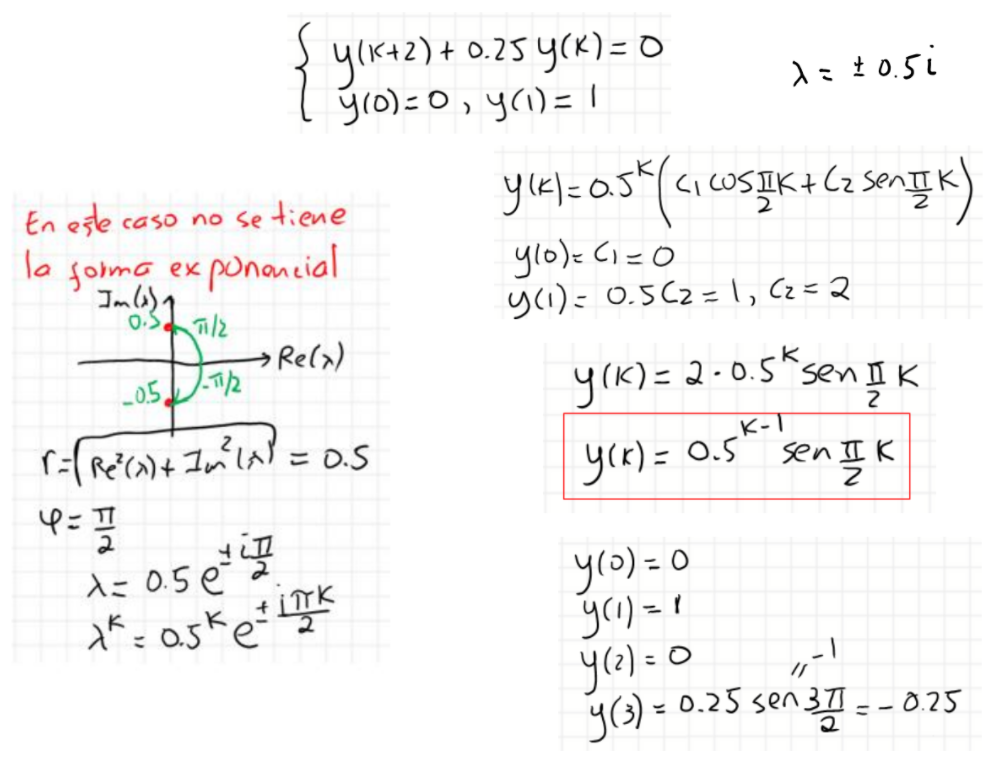

#### Tercer ejemplo de solución analítica: Ceros que no tienen sentido

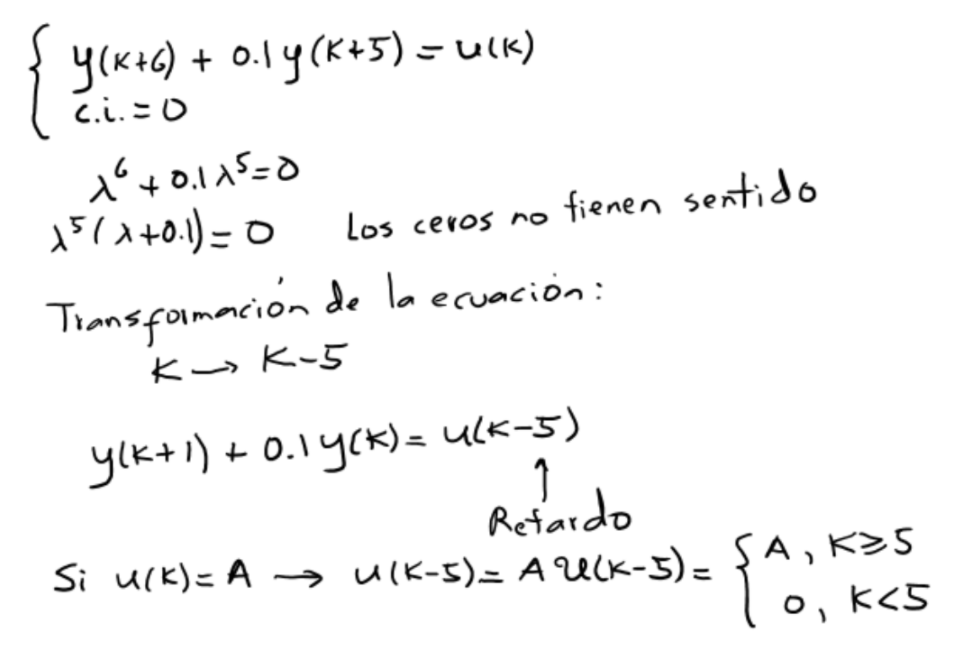

## Clase 4: Transformada de Laplace 

### Definición: Transformada de Laplace


$$L\left\lbrace f\left(t\right)\right\rbrace \equiv \Im \left(s\right)=\int_{0^- }^{\infty } e^{-\textrm{st}} f\left(t\right)\textrm{dt},\;s=\sigma +i\omega$$


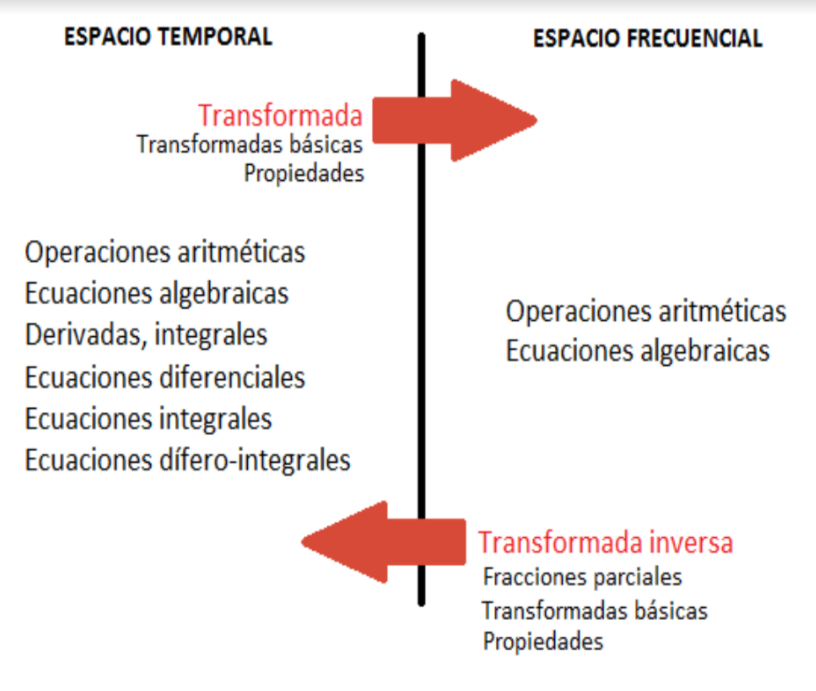

### Transformadas básicas transformada de Laplace

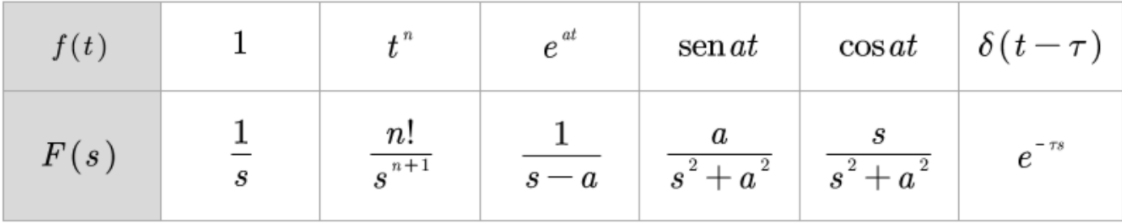

### Propiedades básicas transformada de Laplace

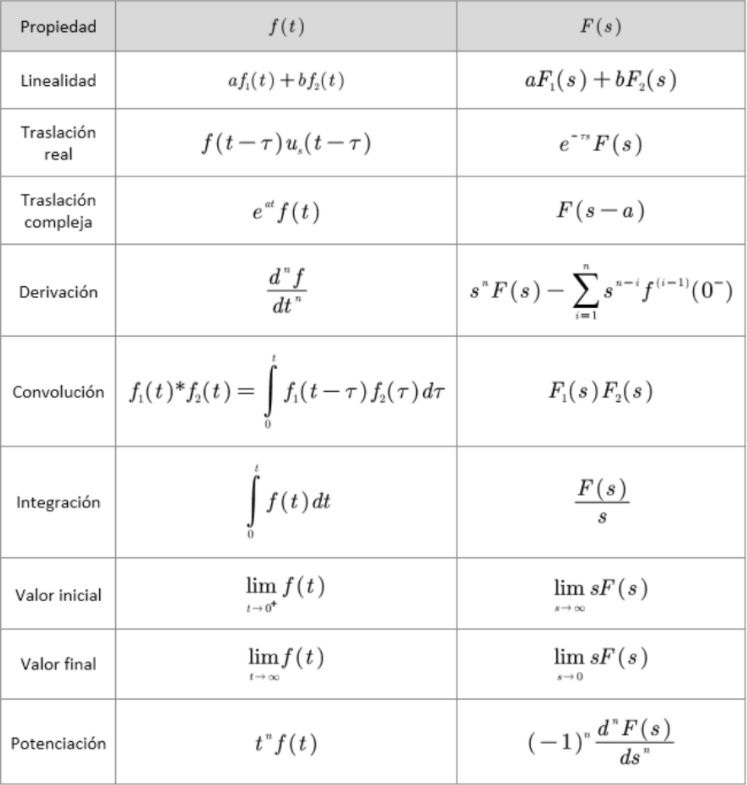

## Clases 5 y 6: Transformada Z

### Concepto de función muestreada

A partir de una función cualquiera $f\left(t\right),t\ge 0$, definiremos la función muestreada $\overset{\star }{f\left(t\right)}$ con intervalo de muestreo $T$ como se sigue


$$\overset{\star }{f\left(t\right)} =f\left(t\right)\sum_{k=0}^{\infty } \delta \left(t-\textrm{kT}\right)=\sum_{k=0}^{\infty } f\left(\textrm{kT}\right)\delta \left(t-\textrm{kT}\right)$$


Debe ser claro que $\overset{\star }{f\left(t\right)} =\left\lbrace \begin{array}{ll}
f\left(t\right)\delta \left(t-\textrm{kT}\right) & t=\textrm{kT},\textrm{para}\;\textrm{algún}\;k=0,1,2,\ldotp \ldotp \ldotp \\
0 & \textrm{en}\;\textrm{otro}\;\textrm{caso}
\end{array}\right.$

### Transformada Z

Aplicando la transformada de Laplace a una función muestreada obtenemos que 

$L\left\lbrace \overset{\star }{f\left(t\right)} \right\rbrace =\sum_{k=0}^{\infty } f\left(\textrm{kT}\right)L\left\lbrace \delta \left(t-\textrm{kT}\right)\right\rbrace =\sum_{k=0}^{\infty } f\left(\textrm{kT}\right)e^{-\textrm{kTs}}$, ahora, haciendo el cambio de variable $z=e^{\textrm{Ts}}$, llegamos a que

$L\left\lbrace \overset{\star }{f\left(t\right)} \right\rbrace =\sum_{k=0}^{\infty } f\left(\textrm{kT}\right)z=Z\left\lbrace f\left(\textrm{kT}\right)\right\rbrace$, adicionalmente, sabiendo que T actúa como una variable muda se sigue que podemos asumir $T=1$ y considerar


$$Z\left\lbrace f\left(\textrm{kT}\right)\right\rbrace =$$

$$\sum_{k=0}^{\infty } f\left(k\right)z^{-k} =\Im \left(z\right)$$


#### Transformadas básicas

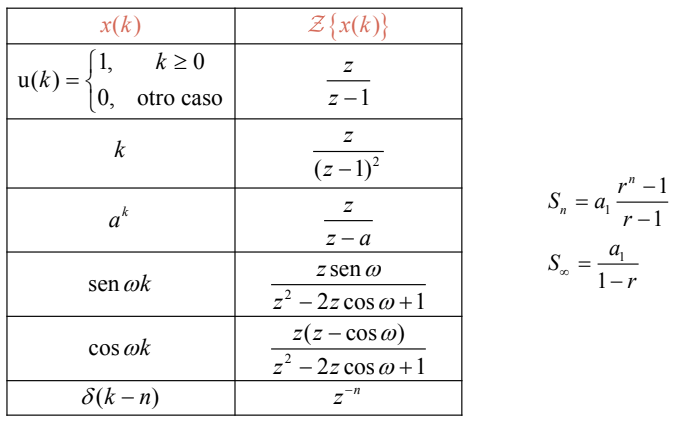

#### Propiedades operacionales

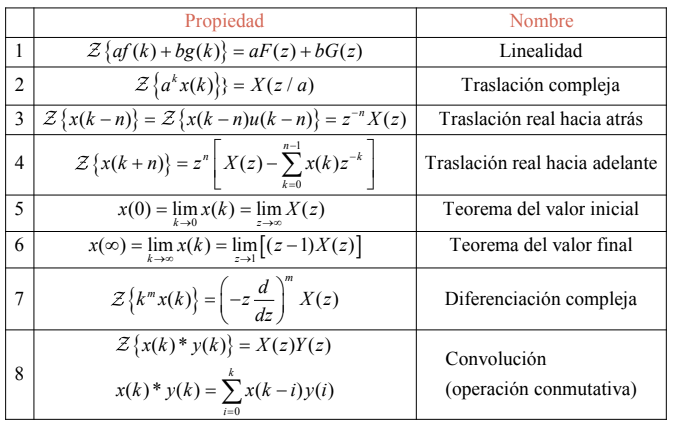

### Transformada Z inversa

Notando que la transformada Z de una función es una fracción propia, es posible calcular la transformada Z inversa mediante procedimientos:

- **Método de la serie infinita de potencias: **Se procede mediante división larga. Los coeficientes de la división corresponden con los valores de la función en cada instante de muestreo. $Y\left(z\right)=\frac{10z}{\left(z-1\right)\left(z-2\right)}=\frac{10z}{z^2 -3z+2}=10z^{-1} +30z^{-2} +70z^{-3} +\ldotp \ldotp \ldotp =\sum_{k=0}^{\infty } f\left(k\right)z^{-k} \Longrightarrow f\left(0\right)=0,f\left(1\right)=10,f\left(2\right)=30,f\left(3\right)=70,\ldotp \ldotp \ldotp$

- **Desarrollo en fracciones parciales: **Se debe garantizar que cada fracción parcial sea una función propia. De forma tal, buscamos reconocer estructuras a partir de las cuales aplicar la tabla de transformadas básicas y propiedades operacionales.

- **Integral de inversión: **Es posible calcular la transformada inversa por definición, sin embargo, será necesario resolver una integral compleja por el teorema del residuo de Cauchy. **Este método no se utiliza en clase.**

### Solución de ecuaciones en diferencias aplicando transformada Z en MatLab

Supongamos que queremos resolver la siguiente ecuación en diferencias sujeta a condiciones iniciales


$$\left\lbrace \begin{array}{ll}
y\left(k+3\right)+0\ldotp 8y\left(k+2\right)=0 & \\
y\left(0\right)=1,y\left(1\right)=0,y\left(2\right)=1 & 
\end{array}\right.$$


#### Solución mediante fracciones parciales

**Solución analítica**

clear;clc
%y(k+3)+0.8*y(k+2)==0 % y(0)=1, y(1)=0, and y(2)=1.
syms y(k) z %se declara la función simbólica y(k) y la variable simbólica z
assume(k>=0 & in(k,'integer')) % se establece que k es entero mayor o igual a 0
f = y(k+3)+0.8*y(k+2)==0 % se declara la ecuación en diferencias

$$f = \frac{4\,y\left(k+2\right)}{5}+y\left(k+3\right)=0$$

fZT = ztrans(f,k,z) %transformada z de la ecuación en diferencias, la variable k pasa a z

$$fZT = \frac{4\,z^{2}\,\mathrm{ztrans}\left(y\left(k\right),k,z\right)}{5}-z\,y\left(2\right)-\frac{4\,z\,y\left(1\right)}{5}+z^{3}\,\mathrm{ztrans}\left(y\left(k\right),k,z\right)-\frac{4\,z^{2}\,y\left(0\right)}{5}-z^{2}\,y\left(1\right)-z^{3}\,y\left(0\right)=0$$

syms pZT %variable para resolver la ecuación
fZT = subs(fZT,ztrans(y(k),k,z),pZT) % se sustituyen las expresiones de Y(z) por la variable simbólica pZT

$$fZT = \frac{4\,\mathrm{pZT}\,z^{2}}{5}-z\,y\left(2\right)-\frac{4\,z\,y\left(1\right)}{5}+\mathrm{pZT}\,z^{3}-\frac{4\,z^{2}\,y\left(0\right)}{5}-z^{2}\,y\left(1\right)-z^{3}\,y\left(0\right)=0$$

pZT = solve(fZT,pZT) % se soluciona la ecuación para pZT=Y(Z)

$$pZT = \frac{4\,y\left(1\right)+5\,y\left(2\right)+4\,z\,y\left(0\right)+5\,z\,y\left(1\right)+5\,z^{2}\,y\left(0\right)}{5\,z^{2}+4\,z}$$

pZT = subs(pZT,[y(0) y(1) y(2)],[1 0 1]) % se sustituyen los valores de las condiciones iniciales para obtener la fracción Y(z)

$$pZT = \frac{5\,z^{2}+4\,z+5}{5\,z^{2}+4\,z}$$

pZT=partfrac(pZT) % esta línea de código ayuda a evidenciar la descomposición en fracciones parciales

$$pZT = \frac{5}{4\,z}-\frac{25}{4\,\left(5\,z+4\right)}+1$$

ySol = iztrans(pZT,z,k) % se aplica la transformada inversa, la variable z pasa a k

$$ySol = \frac{5\,\delta_{k-1,0}}{4}+\frac{25\,{\left(-\frac{4}{5}\right)}^{k}}{16}-\frac{9\,\delta_{k,0}}{16}$$

ySol = simplify(ySol) % de ser posible se simplifica la expresión resultante, esta es la solución de la ecuación en diferencias

$$ySol = \frac{5\,\delta_{k-1,0}}{4}+\frac{25\,{\left(-\frac{4}{5}\right)}^{k}}{16}-\frac{9\,\delta_{k,0}}{16}$$

**Gráfica de la solución analítica**

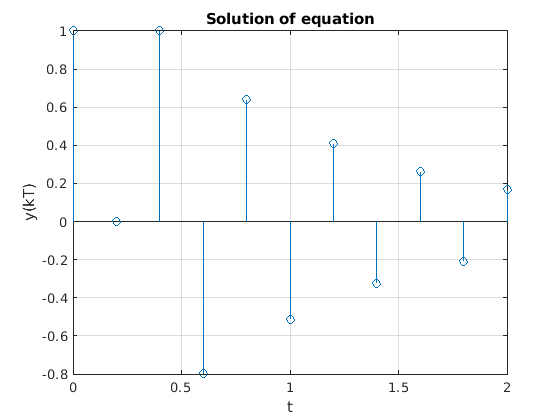

kValues = 0:10; %instantes de muestreo
T=0.2;% intervalo de muestreo
ySolValues = subs(ySol,k,kValues); %evaluamos los valores de k en la solución
ySolValues = double(ySolValues); % pasamos los valores de simbólico a variable numérica
ySolValues = real(ySolValues); % capturamos la parte real de los valores
figure(1)
clf
stem(kValues*T,ySolValues) %gráfica de la función discretizada
title('Solution of equation')
xlabel('t')
ylabel('y(kT)')
grid on

#### Solución mediante la serie infinita de potencias

Para resolver la ecuación mediante la serie infinita de potencias debemos aplicar la transformada Z y llegar a la expresión racional $Y\left(z\right)=\frac{P_1 \left(z\right)}{P_2 \left(z\right)}$. Para el caso del ejemplo que estamos resolviendo tenemos que $Y\left(z\right)=\frac{5z^2 +4z+5}{5z^2 +4z}$. Podemos aplicar la división larga para obtener los primeros 11 valores de la función (equivalentes a los puntos de la gráfica anterior) mediante la función [ldiv](https://www.mathworks.com/matlabcentral/fileexchange/1752-calculates-inverse-z-transform-by-long-division) desarrollada por Tamer Melik. El primer argumento que recibe esta función son los coeficientes del numerados, luego los coeficientes del denominador y finalmente el número de valores de la función por obtener

yvals=ldiv([5,4,5],[5,4],11)

ans =     1.0000         0    1.0000   -0.8000    0.6400   -0.5120    0.4096   -0.3277    0.2621   -0.2097    0.1678


## Clases 7 y 8: Introducción a las funciones de transferencia

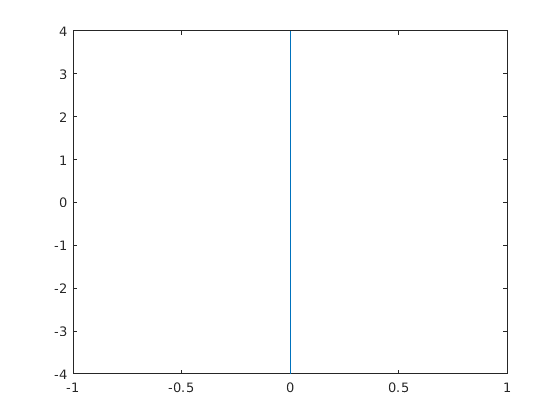

clear;clc
x=[-4:0.001:4]; y=x; x1=x;
y1=zeros(1,length(x));
z=exp(y1+i*x1); th1=abs(z); rho1=angle(z); 
figure(1), plot(y1,x1)

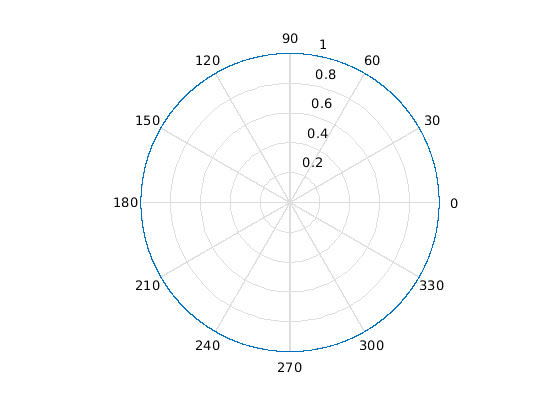

figure(2)
clf
polar(rho1,th1)

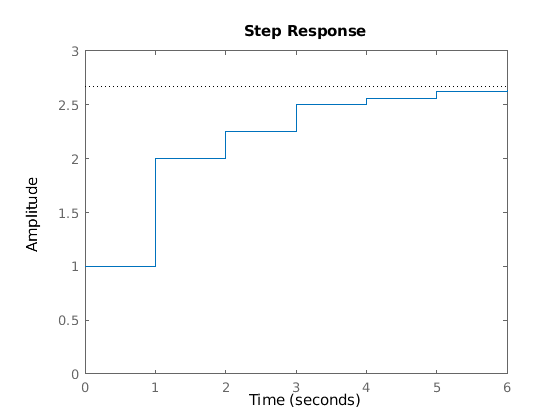

figure(1)
clf
Gd = tf([1  0],[1 0 -0.25],'Ts',1); step(Gd); axis([0,6,0,3])

clear;clc;close all
syms s
A=[0 1;-4 -2];

A =      2     1
     1     2


G=inv(s*eye(2)-A)

$$G = \left(\begin{array}{cc} \frac{s-2}{s^{2}-4\,s+3} & \frac{1}{s^{2}-4\,s+3}\\ \frac{1}{s^{2}-4\,s+3} & \frac{s-2}{s^{2}-4\,s+3} \end{array}\right)$$

simplify([1 0]*G*[0 1]')

$$ans = \frac{1}{s^{2}-4\,s+3}$$

# Funciones adicionales para el curso

function funresult=ldiv(a,b,N)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Function (ldiv) : calculate inverse Z-transform by long division 
% Author : Tamer mohamed samy abdelazim Mellik
% Contact information : 
%Department of Electrical & Computer Engineering,
%University of Calgary,
%2500 University Drive N.W. ,
%Calgary, AB T2N 1N4 ,
%Canada .
% email :abdelasi@enel.ucalgary.ca  
% email : tabdelaz@ucalgary.ca
% Webpage : http://www.enel.ucalgary.ca/~abdelasi/
% Date    : 2-5-2002
% Version : 1.0.0
%Example
% This function like deconv but it help if the numerator less or equal degree of denominator
% if you have this function (It must arranged in terms of minus power of Z):
%              1
% G(z)= -----------------      
%             -1     -2
%      ( 5 - Z  - 3 Z  )
% and you want to calculate long division or inverse Z transform :
% The numerator  is a=[1] and  the denominator is b= [5 -1 -3 ]
% call the function ldiv(a,b) to get the funresult 20 items (default)
% another example :
%                -2     -3 
%       ( 5 - 3 Z  + 4 Z  )
%  G(z)-----------------      
%              -1     -2
%        (5 - Z  - 3 Z )
% a=[5 0 -3 4] , b= [5 -1 -3 ] and you want the funresult 100 terms !
% ldiv(a,b,100) 
% Note : The author doesn't have any responsibility for any harm caused by the use of this file
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%a numerator
%b denominator
%default order of the filter == 20
funresult=[];
if nargin < 3
    if nargin > 1
            N=20;
    else
            disp('Usage: M = ldiv(a,b,N)')
            disp('a:numerator , b denominator and N is the order of the resultant filter')
            return
    end 
end
if size(a) < 1
    disp('Error: numerator must at least have one element not empty')
    return
end
if size(b) < 1
    disp('Error: denominator must at least have one element not empty')
    return
end
if b(1)==0
    disp('Error: The first element of denominator must have nonzero value')
    return
end
if size(b) < 2
    funresult=a./b;
    for i =length(funresult)+1:N
       funresult(i)=0;
    end
    return
end
for i = length(a)+1:N
    a(i)=0;
end
for i = 1 : N
    funresult(i)=a(1)/b(1);
    if length(a)>1
            for k= 2:length(b)
                if k > length(a)
                    a(k)=0;
                end
                a(k)=a(k)-funresult(length(funresult))*b(k);
            end
        for i = 1:length(a)-1
                a(i)=a(i+1);
        end
        a=a(1:length(a)-1);
    end
end
end